mat = generator_3(200);
A = mat(:, 1:end-1);

my_results = Jacobi_solver(mat);
gaus = gaussian_solver(mat);
default_results = matlab_solver(mat);

differences = abs(my_results-default_results);
srednia_roznica_wynikow = mean(differences)

srednia_roznica_wynikow = 3.7564e+114

spectral_radius = max(abs(eig(A)))

spectral_radius = 0.4719

check(A)

warunek dostateczny NIE spelniony


ans = logical
   0


mat = generator_1(600);
        A = mat(:, 1:4);
        ground = mat(:, 5);
        
        results = Jacobi_solver(mat);
        %built in function for comparison purposes
        
        A_dims = size(A);
        n_rows = A_dims(1);
        n_cols = A_dims(2);
        values_computed = zeros(n_rows, 1);
        for n=1 : n_rows
            Sum = 0;
            for k=1: n_cols
                Sum  = Sum + A(n, k) * results(k);
            end
            values_computed(n) = Sum;
        end
        differences = values_computed-ground;
        pow_differences = differences.^2;
        error = sqrt(sum(pow_differences, 'all'))

error = 9.0876

roznice = test_stopu(mat)

roznice =    13.0929
   11.2037
    9.5952
    8.2176
    7.0392
    6.0298
    5.1657
    4.4254
    3.7915
    3.2484


indexes = 25:1:100

indexes =     25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74


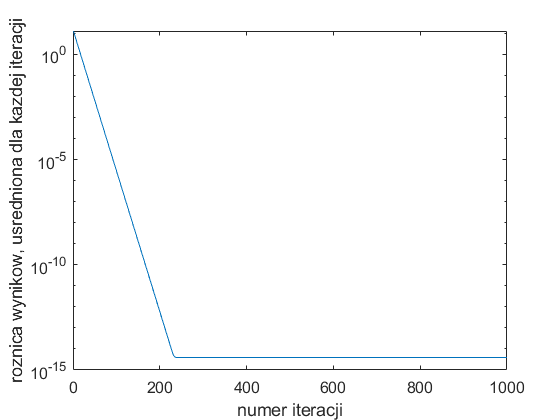

semilogy(roznice);
xlabel('numer iteracji');
ylabel('roznica wynikow, usredniona dla kazdej iteracji');
    ax1 = gca;
    ax1.FontSize = 12;